# Using RK4 to solve Ordinary Differential Equations

In this exercise, you are going to build your own ODE solver by creating a function called $myode()$. To do this, you are going to use the 4th order Runge-Kutta (RK) method. 

clear; clf;

The first step is to identify the ODE you wish to solve. Let's use the function that's in the example in the video lecture in the VLE. In the field below, translate to code the ODE 

$\frac{\textrm{dy}}{\textrm{dx}}=-2x^3 +12x^2 -20x+8\ldotp 5$.

Use either symbolic math or define a new MATLAB function. If you are using symbolic math, type the equation in the field below. Otherwise, leave the field below blank and create a new MATLAB script that accepts two arguments. The first are the individual values of the $x$ data set, and the second is the initial condition, $y=1$ at $x=0$. You will need to submit the MATLAB script that is your MATLAB function, along with your solution to this MP. Use the variable $f$ for the mathematical function.

f = @(x,y) -2*x^3 + 12*x^2 + -20*x + 8.5;

You now need to select a a step size, $h$. Remember to select an appropriate step size. If it's too large, then the accuracy is sacrificed. If it's too small, then the computing efficiency is sacrificed.

h = 0.1;

Then, you need to select a range of values for $x$. You may select the same range as in the example in the video lecture, i.e. $x=0$ to $x=4$.

x = 0:h:4;

At this point, you will need to open a new MATLAB script to create a function called $myode()$. This function will have two arguments as input. The first argument is the $x$ data set, while the second argument is the initial condition $y=1$ at $x=0$. Develop the script for your MATLAB function $myode()$ and implement RK4. Call your MATLAB function to numerically solve the given ODE and assign the output to the variable $y$.

y = myode(x,1);

Plot the numerical solution (red solid circles) against the analytical solution (black line, line width = 3). The analytical solution is easily solved, which you can do by hand. Add a title and appropriate x- and y-labels.

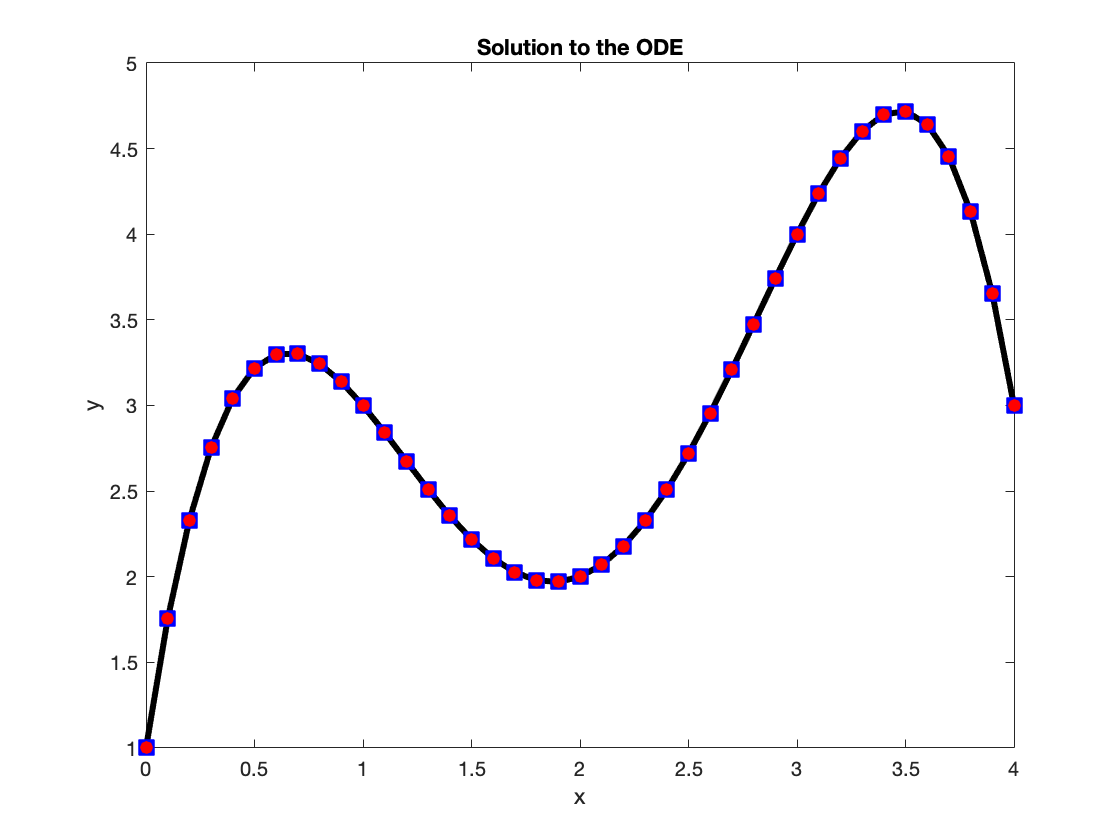

% Solving for the analytical solution, we get
ysol = -0.5*x.^4 + 4*x.^3 - 10*x.^2 + 8.5*x + 1;
[xode45,yode45] = ode45(f,x,1);

clf
plot(x,ysol,'k',"LineWidth",3)
hold on
plot(xode45,yode45,'bs',"MarkerFaceColor",'b',"MarkerSize",10)
plot(x,y,'ro',"MarkerFaceColor",'r')
title("Solution to the ODE")
xlabel("x")
ylabel("y")
% ylim([0 8])
hold off

Finally, compare your solution obtained from your function $myode()$ with the built-in MATLAB $ode45()$ function, and add this new solution to the plot. Use blue solid squares for this solution.

yode45 = ode45(f,x,y(1));